%Import the audio and convert to mono-channel if required
[audio, Fs] = audioread(".\bells-melody-loop-266598.wav");
if size(audio, 2) == 2
    audio = mean(audio, 2);
end

disp(Fs);

       44100




% Upsameple the audio
audio_up = resample(audio, 2, 1);
Fs_new = Fs * 2;

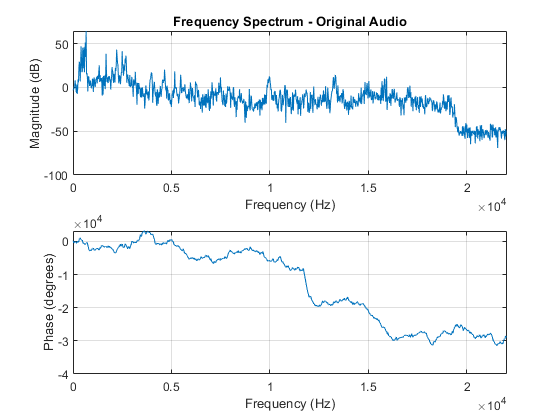

% Plot normal and upsampled audio
figure;
freqz(audio, 1, 1024, Fs);
title('Frequency Spectrum - Original Audio');

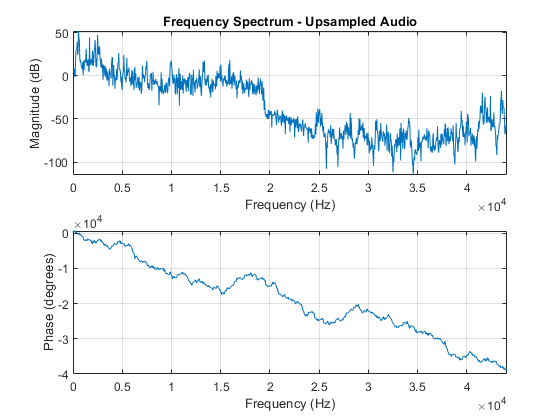


figure;
freqz(audio_up, 1, 1024, Fs_new);
title('Frequency Spectrum - Upsampled Audio');

% Getting the useful range of frequenceies to put the interfernece outside
% of that range
N = length(audio);
f = linspace(0, Fs/2, N/2); 
Audio_FFT = abs(fft(audio));
threshold = max(Audio_FFT) * 0.05;

audio_freq_range = f(Audio_FFT(1:N/2) > threshold);

min_freq = min(audio_freq_range);
max_freq = max(audio_freq_range);
fprintf('Audio Frequency Range: %.2f Hz - %.2f Hz\n', min_freq, max_freq);

Audio Frequency Range: 308.13 Hz - 2679.55 Hz


% Add interfernce to normal and upsampled signals
t_up = (0:length(audio_up)-1)/Fs_new;
f_interf = max_freq*4; 
interf_up = 0.5 * sin(2*pi*f_interf*t_up)';
audio_up_interf = audio_up + interf_up;

t = (0:length(audio)-1);
f_interf = max_freq*4; 
interf = 0.5 * sin(2*pi*f_interf*t)';
audio_interf = audio + interf;

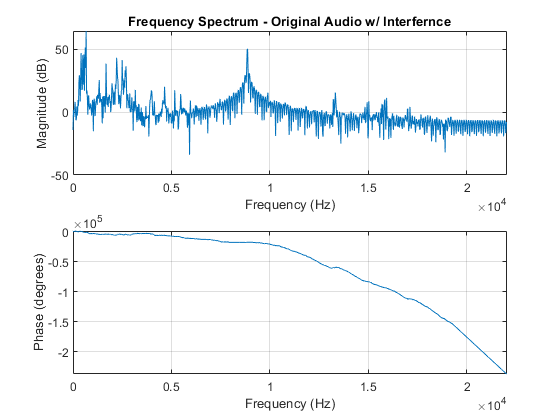

% Plot normal and upsampled audio
figure;
freqz(audio_interf, 1, 1024, Fs);
title('Frequency Spectrum - Original Audio w/ Interfernce');

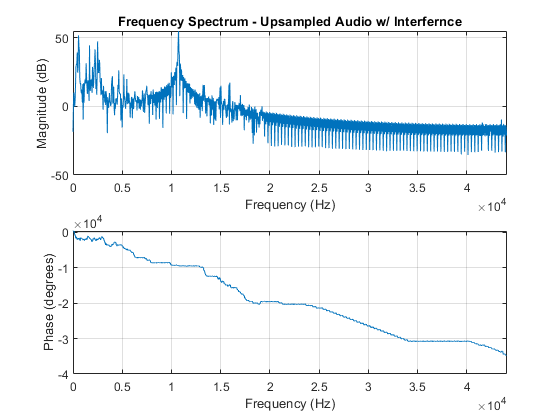


figure;
freqz(audio_up_interf, 1, 1024, Fs_new);
title('Frequency Spectrum - Upsampled Audio w/ Interfernce');

s_u = audioplayer(audio_up, Fs_new);
s_u_n = audioplayer(audio_up_interf, Fs_new);

if (exist("s_u_d", "var"))
    s_u_d.pause;
end
if (exist("s_u", "var"))
    s_u.pause;
end
if (exist("s_u_n", "var"))
    s_u_n.pause;
end

play_sound = "sound"

play_sound = "sound"

switch (play_sound)
    case "sound"
        s_u.play;
    case "sound_w_noise"
        s_u_n.play;
end
 

 
if (exist("s_u_d", "var"))
    s_u_d.pause
end
if (exist("s_u", "var"))
    s_u.pause
end
if (exist("s_u_n", "var"))
    s_u_n.pause
end

The designed filter:

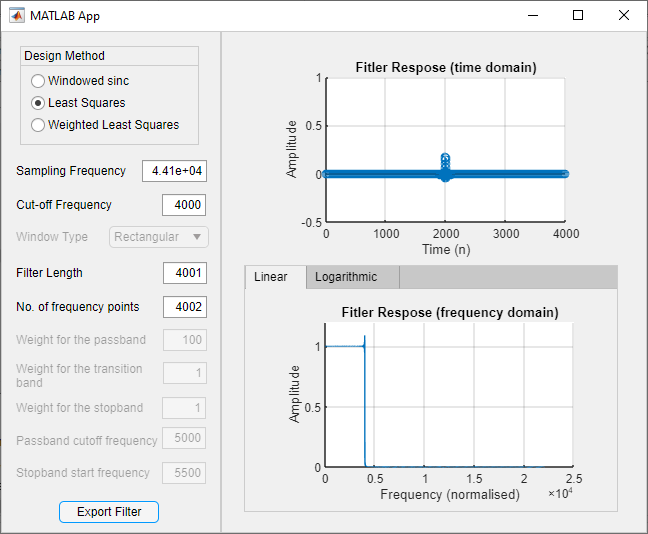'

**How was it chosen?**

Earlier we knew that our audio's maximum useful frequency is 2680

By looking at the spectum of the audio signal was added we can see that the noise is added at a point of 10,000Hz which is 4 times higher than our useful frequency.

We decided to pick a middleground for our cutoff so we picked a frequency of 4000Hz, it is safely out of range of the useful frequencies of the audio and its far enough away from the noise to ensure the attuenuation will be maximized.

We first attempted lower order (less length) windowed sinc filters however the noise was not properly removed and we needed to run it though the filter multiple times to see a good effect on the noise removal.

We then readjusted our paramaters and chose weighted least squared and reached an almost ideal noise removal, where we cannot see or hear the noise anymore in our audio.

filter_struct = load("filter.mat").filter_specs;
filter = filter_struct.filter_time_domain;

filter_table = table(...
    filter_struct.filter_L, ...
    string(filter_struct.filter_win_type), ...
    filter_struct.filter_fs, ...
    filter_struct.filter_fc, ...
    filter_struct.filter_k, ...
    'VariableNames', {'FilterLength', 'WindowType', 'SamplingFreq', 'CutoffFreq', 'Gain'});
disp("Filter specs: ")

Filter specs: 


disp(filter_table);

    FilterLength     WindowType      SamplingFreq    CutoffFreq    Gain
    ____________    _____________    ____________    __________    ____

        4001        "Rectangular"       44100           4000       4002



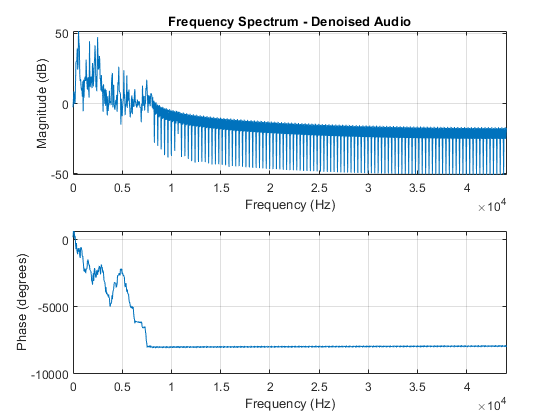

audio_denoised = conv(audio_up_interf, filter, "same");

figure;
freqz(audio_denoised, 1, 1024, Fs_new);
title('Frequency Spectrum - Denoised Audio');


figure;
freqz(audio_up, 1, 1024, Fs_new);
title('Frequency Spectrum - Upsampled Audio');


figure;
freqz(audio_up_interf, 1, 1024, Fs_new);
title('Frequency Spectrum - Upsampled Audio w/ Interfernce');

s_u_d = audioplayer(audio_denoised, Fs_new);
if (exist("s_u_d", "var"))
    s_u_d.pause;
end
if (exist("s_u", "var"))
    s_u.pause;
end
if (exist("s_u_n", "var"))
    s_u_n.pause;
end

play_sound_denoise = "sound_denoised"

play_sound_denoise = "sound_denoised"

switch (play_sound_denoise)
    case "sound_denoised"
        s_u_d.play;
    case "sound_w_noise"
        s_u_n.play;
    case "sound_upsampled"
        s_u.play;
end
 

 
if (exist("s_u_d", "var"))
    s_u_d.pause;
end
if (exist("s_u", "var"))
    s_u.pause;
end
if (exist("s_u_n", "var"))
    s_u_n.pause;
end